# Force Sensor Pyramid Data Analysis

We import the struct with all the data and analyse it here. Firstly, we need to do singal noise removal on the four channels of force sensor data and one of acceleration. 

#### Filter the voltage data.

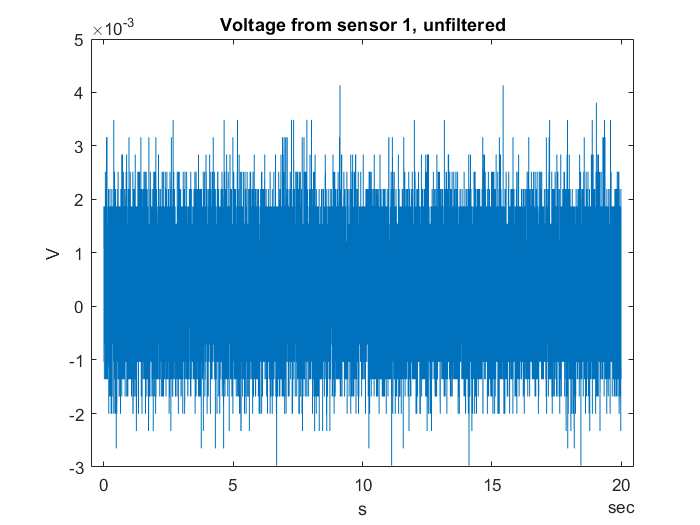

%import the data
load("initialForceTest.mat")

%get out the voltages (tetrahedral)
voltages = [illuminatiData.forces.cDAQ2Mod1_ai0,illuminatiData.forces.cDAQ2Mod1_ai1,...
    illuminatiData.forces.cDAQ2Mod1_ai2,illuminatiData.forces.cDAQ2Mod1_ai3];
timeSpan = illuminatiData.forces.Time;

%plot the data without signal conditioning
figure(1)
clf
plot(timeSpan,voltages(:,1));
title("Voltage from sensor 1, unfiltered")
xlabel('s')
ylabel('V')

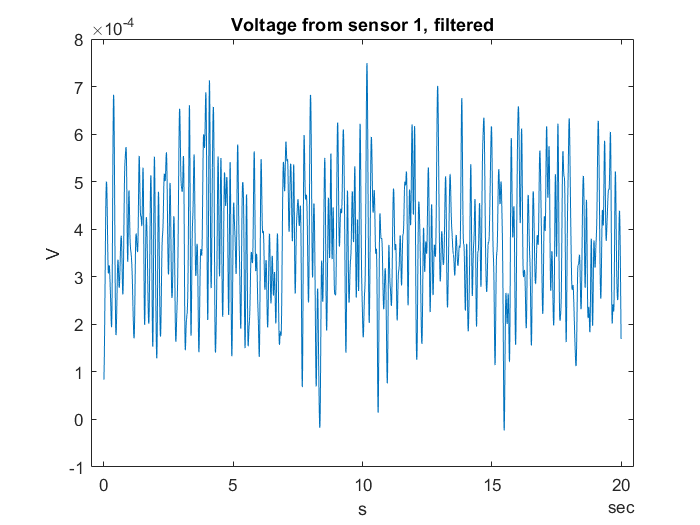

%set the sampling frequency
fs = illuminatiData.fs;
fs = 10000;

%set the cutoff frequency
freqCutoff = 20;

%get the filtered signal
filteredVoltages = zeros(size(voltages));
for i = 1:size(voltages,2)
    filteredVoltages(:,i) = lowpass(voltages(:,i),20,fs,'Steepness',0.98);
end

%plot the data with filtering
figure(2)
clf
plot(timeSpan,filteredVoltages(:,1));
title("Voltage from sensor 1, filtered")
xlabel('s')
ylabel('V')

#### Convert the voltage into force data and into xyz coordinates and plot.

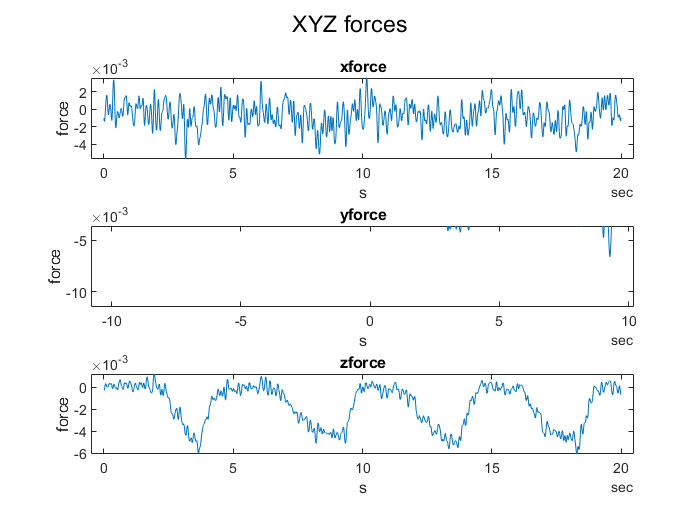

%convert using the conversion function
[zforce,yforce,xforce] = tetForcesToXYZ(filteredVoltages(:,1),filteredVoltages(:,2),filteredVoltages(:,3),filteredVoltages(:,4),10);

%now we can plot the xyz force over time
figure(3)
clf
subplot(3,1,1)
plot(timeSpan,xforce)
title("xforce");
xlabel("s")
ylabel("force")

subplot(3,1,2)
plot(timeSpan,yforce)
title("yforce");
xlabel("s")
ylabel("force")

subplot(3,1,3)
plot(timeSpan,zforce)
title("zforce");
xlabel("s")
ylabel("force")
sgtitle("XYZ forces");

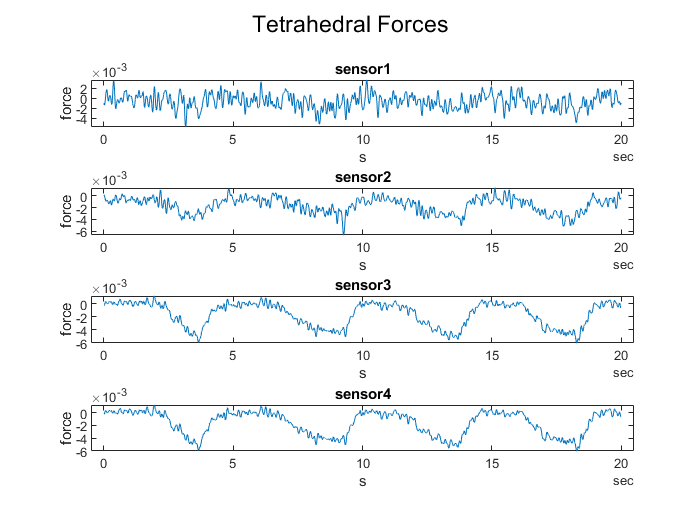

%also the tetrahedral forces over time
%now we can plot the xyz force over time
figure(4)
clf
subplot(4,1,1)
plot(timeSpan,xforce)
title("sensor1");
xlabel("s")
ylabel("force")

subplot(4,1,2)
plot(timeSpan,yforce)
title("sensor2");
xlabel("s")
ylabel("force")

subplot(4,1,3)
plot(timeSpan,zforce)
title("sensor3");
xlabel("s")
ylabel("force")
sgtitle("XYZ forces");

subplot(4,1,4)
plot(timeSpan,zforce)
title("sensor4");
xlabel("s")
ylabel("force")
sgtitle("Tetrahedral Forces");

%plot the acceleration

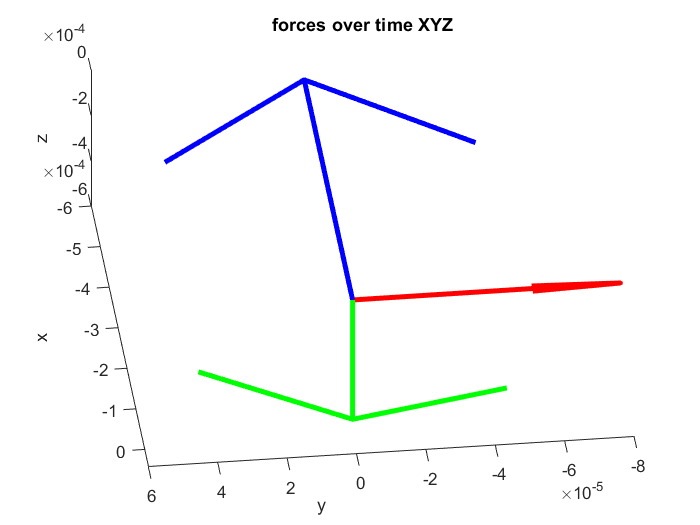

%plot the forces as an animation using arrows
figure(5)
clf
hold on
for i = 1:size(xforce,1)
    drawVector([0 0 0],[0 yforce(i,1) 0],'r');
    drawVector([0 0 0],[0 0 zforce(i,1)],'g');
    drawVector([0 0 0],[xforce(i,1) 0 0],'b');
    view([-83.261554 -62.592053])
    axis equal
    xlabel('x')
    ylabel('y')
    zlabel('z')
    title('forces over time XYZ')
    pause(0.01)
    clf
end